
%Thomas Wilson B00836766   LAB 5

%section 1
G = tf (8, [1, 10, 31, 30])

G =
 
             8
  ------------------------
  s^3 + 10 s^2 + 31 s + 30
 
Continuous-time transfer function.



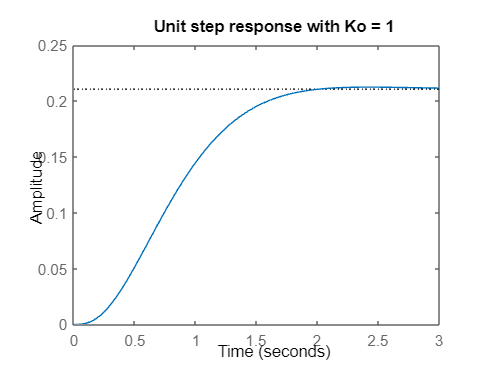

Kp = 1; % Controller with only P configuration
name = sprintf ('Unit step response with Ko = 1' );
plotCLTF( K_p, G, name ); % Unit step response of the CLTF with K_p as a p-only controller


% the system is the balance of all with a quick enough responce to a steady
% state of 1, with no overshoots allowing the system to run efficently


%SECTION 2
 % Unit step response of the CLTF with K_p as a P-only controller
 %having a higher P figure increases the steady state but also durastically
 %increases the overshoot to an unacceptable level.
 %due to this overshoot it takes longer to settle.


K_p2 = 3.11 % Enter a new value of your choice for the P Controller

K_p2 = 3.1100

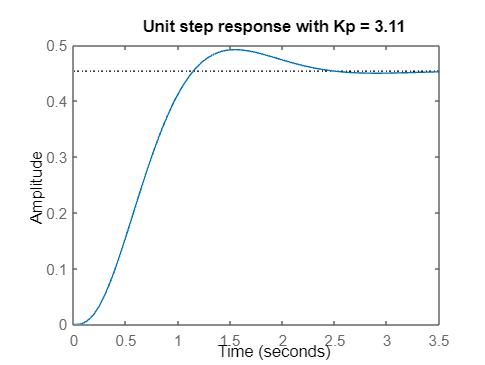

name = sprintf( 'Unit step response with Kp = %.2f', K_p2 );
plotCLTF( K_p2, G, name ); % Unit step response of the CLTF with K_p as a p-only controller

% What deduction can you obtain from the simulations using K_p and K_p2?
% Explain this from the points of the steady-state error,
%e_ss, as well as
% the overall responses of the system, 1.. overshoot, oscillations, faster
% slower responses in terms
% settling time, Ts,
% Record this discussion in your Log Book »

%SECTION 3
% Determine by hand calculations, using Routh-Hurwitz Stability Criterion,
% the value of K that will produce a marginally stable response for the
% CLTF.

% *Hint: Refer to Tutorial 6.

% Record all hand calculations in your Log Book.
% Uncomment, i.e. remove the & signs at the beginning of the codes below
%after you have solved the Routh-Hurwitz Stability Criterion calculations
% exercise.

K_U = 35 % Update K value with the one obtained via calculations

K_U = 35

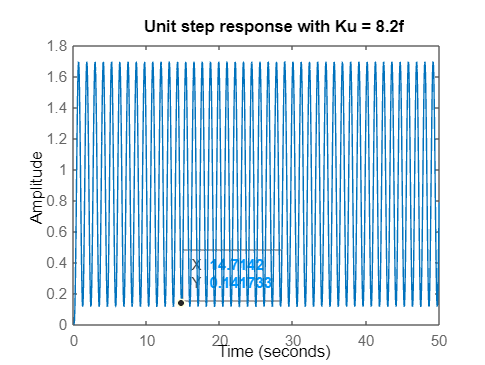

name = sprintf( 'Unit step response with Ku = 8.2f', K_u );
plotCLTF( K_U, G, name ); % Unit step response of the CLTF with K as Ultimate Gain


% From this new unit step response plot, ensure that the closed-loop system
% is marginally stable (sustained oscillations)
%Determine the period of oscillations, Tu, from the plot. You can use the
% Data Cursor button on your plot window,
%shown in Figure 3, to place
%markers on strategic locations on the graph line, e.g. peaks, to know
%specific values of time. You can place more than one data marker

%SECTION 4
% Assume now that the system 15 controlled using a PID controller as shown
% in Figure 2 in the practical manual.
% usino the values of Ku and Tu, employ the Ziegler-Nichols Continuous
%@velina Method to deston the kl
%Ti, and Td parameters for a PID
%controller
%Record all hand calculations in your Log boox.**
%Hint: Ziegler-Nichols Continuous Cycling Method Table can be found in
%Lecture 7 Controllers.

%SYSTEM IS MARGINALLY STABLE 

%signs at the beginning of the codes below
%after you have computed the parameters for the PiD controller.
K_1 = 20.589 % Enter K1 value here

K_1 = 20.5890

T_i = 0.564 % Enter T1 value here

T_i = 0.5640

T_d = 0.141 % Enter Id value here

T_d = 0.1410

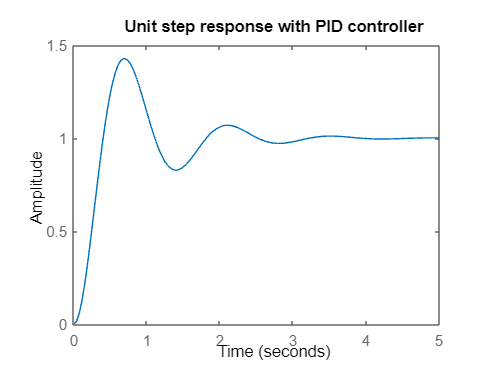

K_PID = K_1 * (1 + tf( 1, [T_i 0] ) + tf( [T_d 0], 1 ) ); % Update controller with PID configuration
name = sprintf('Unit step response with PID controller');
plotCLTF(K_PID, G, name); % Unit step response of the CLTF with X as PID controller